%% DATOS
filename='quenan1.5dpcf2jk.json';
jsontext=fileread(filename);
data=jsondecode(jsontext);
disp(data); 

    protected: [1×1 struct]
    signature: '60700e64f9faaef7531afe056b7be187fcf76f5c5876b62952278548b29adf4f'
      payload: [1×1 struct]



valores =data.payload.values;

%toma datos cada 16 ms osea frecuencia de 62.5Hz

ax = valores(:,1); %m/s^2
ay = valores(:,2); %m/s^2
az = valores(:,3); %m/s^2
wx = valores(:,4); %deg/s
wy = valores(:,5); %deg/s
wz = valores(:,6); %deg/s


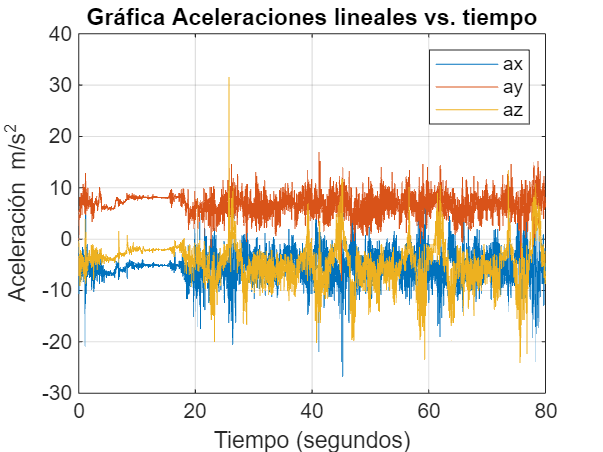

%Periodo
time = (0:size(valores, 1)-1) * 0.016;  % Crear un vector de tiempo desde 0 hasta el final
% Graficar
figure;  % Crear una nueva figura
plot(time, ax, time,ay,time,az);  % Graficar el parámetro en función del tiempo
legend('ax','ay','az');
xlabel('Tiempo (segundos)');  % Etiqueta para el eje x
ylabel('Aceleración m/s^2');  % Etiqueta para el eje y
title('Gráfica Aceleraciones lineales vs. tiempo');  % Título de la gráfica
grid on;  % Activar la cuadrícula

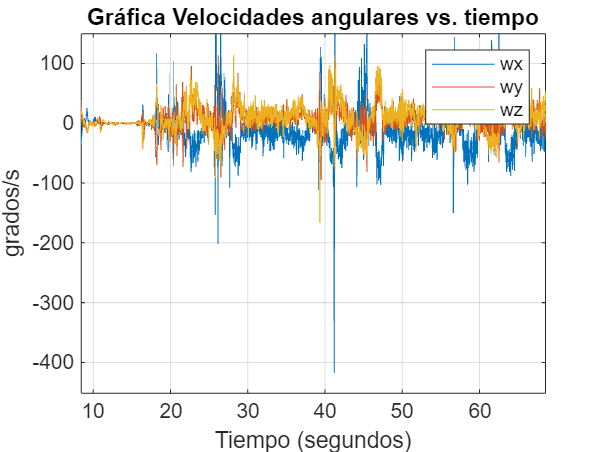

%% VELOCIDADES ANGULARES wx
%Periodo
time = (0:size(valores, 1)-1) * 0.016;  % Crear un vector de tiempo desde 0 hasta el final
% Graficar
figure;  % Crear una nueva figura
plot(time, wx, time,wy,time,wz);  % Graficar el parámetro en función del tiempo
legend('wx','wy','wz');
xlabel('Tiempo (segundos)');  % Etiqueta para el eje x
ylabel('grados/s');  % Etiqueta para el eje y
title('Gráfica Velocidades angulares vs. tiempo');  % Título de la gráfica
grid on;  % Activar la cuadrícula


%Normaacc= for norm[ax ay az]

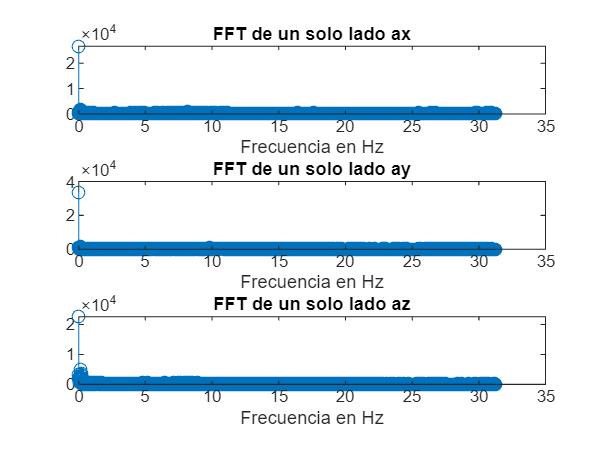

%% SACAR LA FFT QUE ARGUMENTE EL FILTRO 

fs = 62.5; %Hz frecuencia de muestreo
T = 1/fs; % s periodo de muestreo  
N = 5000; % # de muestras
t = (0:N-1)*T; %vector de tiempo

%Transformadas de Fourier para cada aceleración por eje
fftax= fft(ax); 
fftay= fft(ay);
fftaz= fft(az);

k= 0:(N/2);
freq=k*fs/N;

figure;
subplot(3,1,1);
stem(freq,abs(fftax(1:(N/2)+1)));
title('FFT de un solo lado ax');
xlabel('Frecuencia en Hz');

subplot(3,1,2);
stem(freq,abs(fftay(1:(N/2)+1)));
title('FFT de un solo lado ay');
xlabel('Frecuencia en Hz');

subplot(3,1,3);
stem(freq,abs(fftaz(1:(N/2)+1)));
title('FFT de un solo lado az');
xlabel('Frecuencia en Hz');

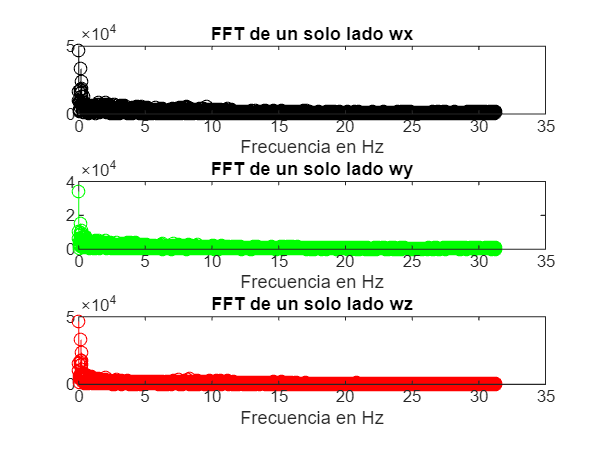


%Transformadas de Fourier para cada velocidad angular por eje
fftwx= fft(wx);
fftwy= fft(wy);
fftwz= fft(wz);

k= 0:(N/2);
freq=k*fs/N;

figure;
subplot(3,1,1);
stem(freq,abs(fftwx(1:(N/2)+1)),'k');
title('FFT de un solo lado wx');
xlabel('Frecuencia en Hz');

subplot(3,1,2);
stem(freq,abs(fftwy(1:(N/2)+1)),'g-');
title('FFT de un solo lado wy');
xlabel('Frecuencia en Hz');

subplot(3,1,3);
stem(freq,abs(fftwz(1:(N/2)+1)),'r-');
title('FFT de un solo lado wz');
xlabel('Frecuencia en Hz');

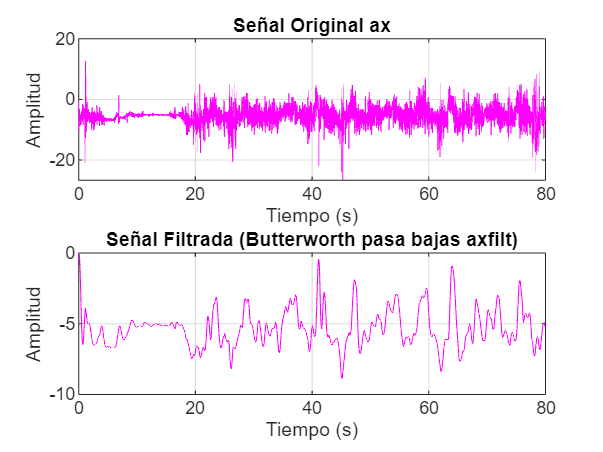

% Parámetros de la señal
% Frecuencia de muestreo en Hz
%t = 0:1/fs:10; % Vector de tiempo de 10 segundos
%signal = sin(2*pi*1*t) + sin(2*pi*5*t); % Señal de ejemplo: 1 Hz + 5 Hz

% Diseño del filtro Butterworth
fc = 1; % Frecuencia de corte (1 Hz)
order = 3; % Orden del filtro (puedes ajustar este valor)
[b, a] = butter(order, fc/(fs/2), 'low'); % Coeficientes del filtro pasa bajas

% Filtrar la señal
axfilt = filter(b, a, ax);
ayfilt = filter(b, a, ay);
azfilt = filter(b, a, az);

wxfilt = filter(b, a, wx);
wyfilt = filter(b, a, wy);
wzfilt = filter(b, a, wz);

% Visualización de la señal original y filtrada
figure;
%para ax
subplot(2, 1, 1);
plot(t, ax, 'm-');
title('Señal Original ax');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, axfilt, 'm-');
title('Señal Filtrada (Butterworth pasa bajas axfilt)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

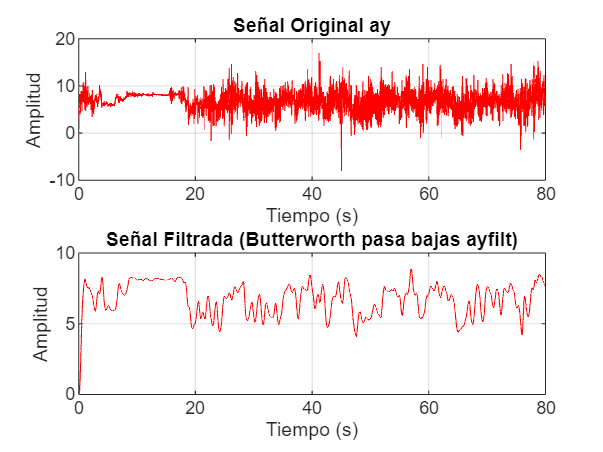


figure;
%para ay
subplot(2, 1, 1);
plot(t, ay, 'r-');
title('Señal Original ay');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, ayfilt, 'r-');
title('Señal Filtrada (Butterworth pasa bajas ayfilt)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

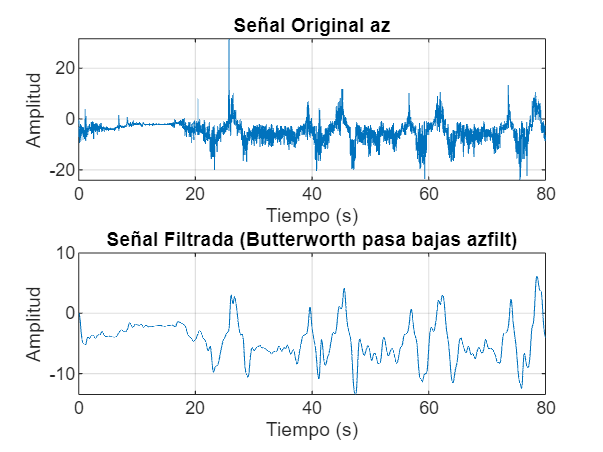


figure;
%para az
subplot(2, 1, 1);
plot(t, az);
title('Señal Original az');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, azfilt);
title('Señal Filtrada (Butterworth pasa bajas azfilt)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

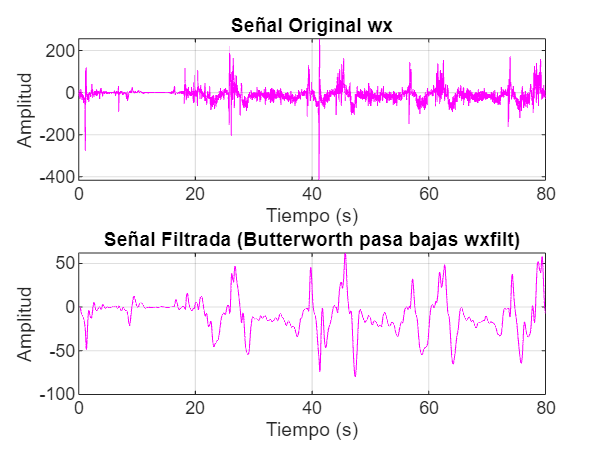



figure;
%para wx
subplot(2, 1, 1);
plot(t, wx, 'm');
title('Señal Original wx');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, wxfilt, 'm');
title('Señal Filtrada (Butterworth pasa bajas wxfilt)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

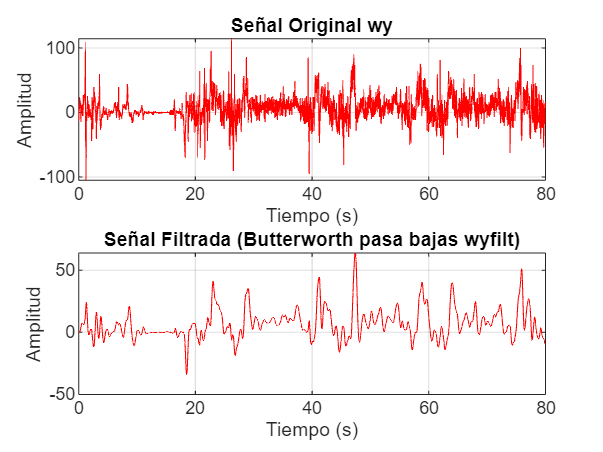


figure;
%para wy
subplot(2, 1, 1);
plot(t, wy, 'r');
title('Señal Original wy');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, wyfilt, 'r');
title('Señal Filtrada (Butterworth pasa bajas wyfilt)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

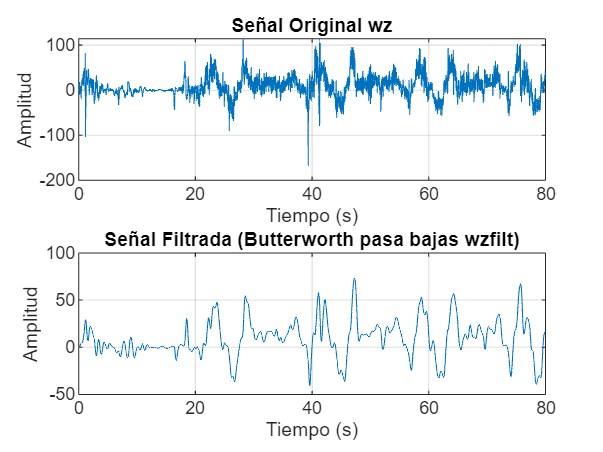


figure;
%para wz
subplot(2, 1, 1);
plot(t, wz);
title('Señal Original wz');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, wzfilt);
title('Señal Filtrada (Butterworth pasa bajas wzfilt)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

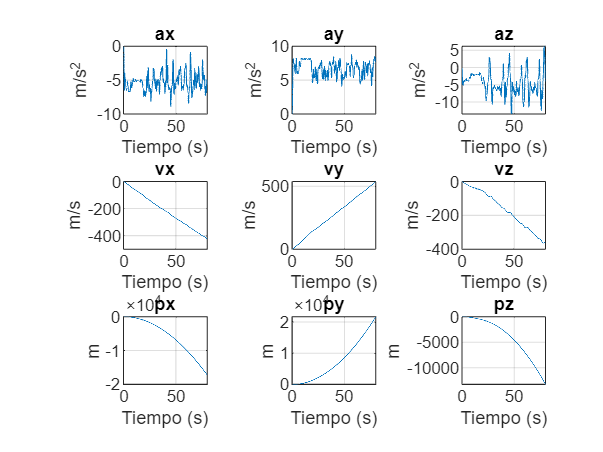

%% INTEGRAR AX, AY Y AZ PARA QUE DE VX, VY Y VZ


% Integrar el vector de datos (señal) usando cumtrapz
vx = cumtrapz(t, axfilt);
vy = cumtrapz(t, ayfilt);
vz = cumtrapz(t, azfilt);

% Integrar el vector de datos (señal) usando cumtrapz
px = cumtrapz(t, vx);
py = cumtrapz(t, vy);
pz = cumtrapz(t, vz);


% Graficar la señal original y su integral ax vx px
figure;
subplot(3,3,1);
plot(t, axfilt);
title('ax');
xlabel('Tiempo (s)');
ylabel('m/s^2');
grid on;

subplot(3,3,4);
plot(t, vx);
title('vx');
xlabel('Tiempo (s)');
ylabel('m/s');
grid on;

subplot(3,3,7);
plot(t, px);
title('px');
xlabel('Tiempo (s)');
ylabel('m');
grid on;

% ay vy py

subplot(3,3,2);
plot(t, ayfilt);
title('ay');
xlabel('Tiempo (s)');
ylabel('m/s^2');
grid on;

subplot(3,3,5);
plot(t, vy);
title('vy');
xlabel('Tiempo (s)');
ylabel('m/s');
grid on;

subplot(3,3,8);
plot(t, py);
title('py');
xlabel('Tiempo (s)');
ylabel('m');
grid on;

%
subplot(3,3,3);
plot(t, azfilt);
title('az');
xlabel('Tiempo (s)');
ylabel('m/s^2');
grid on;

subplot(3,3,6);
plot(t, vz);
title('vz');
xlabel('Tiempo (s)');
ylabel('m/s');
grid on;

subplot(3,3,9);
plot(t, pz);
title('pz');
xlabel('Tiempo (s)');
ylabel('m');
grid on;

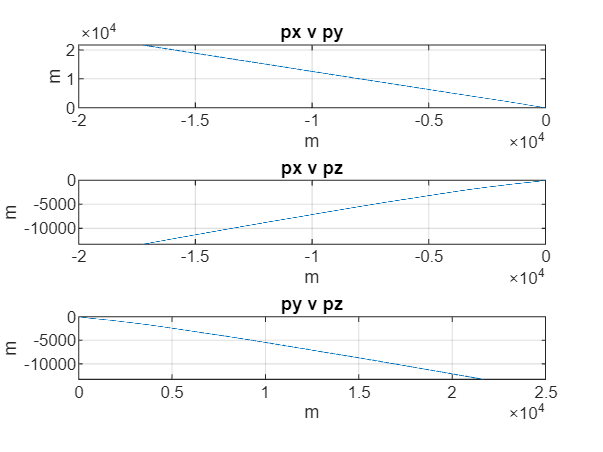

%Gráficas de la segunda derivada de la aceleración lineal (Posición VS Posición de cada eje)
figure;
subplot(3,1,1);
plot(px,py);
title('px v py');
xlabel('m');
ylabel('m');
grid on;

subplot(3,1,2);
plot(px,pz);
title('px v pz');
xlabel('m');
ylabel('m');
grid on;

subplot(3,1,3);
plot(py,pz);
title('py v pz');
xlabel('m');
ylabel('m');
grid on;

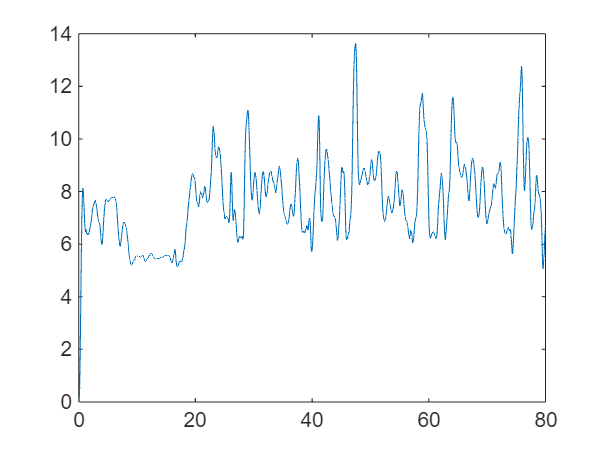


% Ejemplo de vectores ax, ay, az

% Inicializamos el vector donde se almacenarán las normas
norma_acc = zeros(1, length(ax));

% Ciclo for para calcular la norma en cada instante
for i = 1:length(ax)
    norma_acc(i) = sqrt(axfilt(i)^2 + azfilt(i)^2);
end

% Mostrar las normas
%disp('Normas:');
%disp(norma_acc);
figure
plot(t,norma_acc)

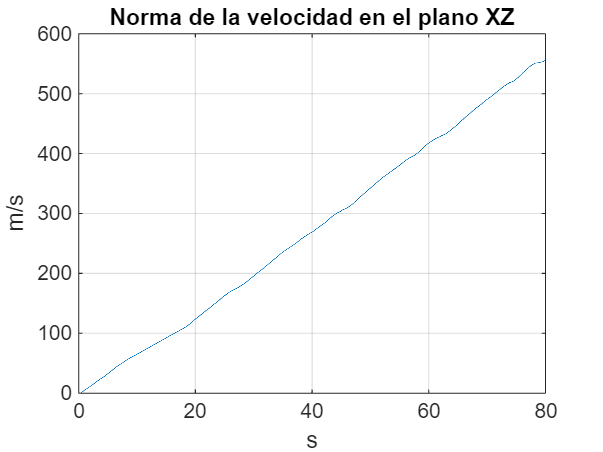


%Generación de la magnitud de la velocidad lineal por cada instante de
%tiempo
for i = 1:length(ax)
    norma_vel(i) = sqrt(vx(i)^2 + vz(i)^2);
end
figure
plot(t,norma_vel)
title('Norma de la velocidad en el plano XZ')
xlabel('s');
ylabel('m/s');
grid on






% norma_vel = cumtrapz(t,norma_acc);
% figure;
% title('norma_vel')
% plot(t,norma_vel)
% 
% norma_pos = cumtrapz(t,norma_vel);



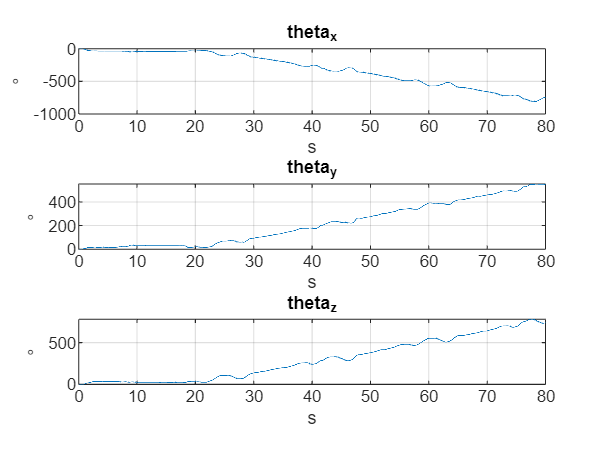

%Generación del ángulo del dispositivo para cada eje como resultado de la
%integración de las velocidades angulares filtradas

theta_x=cumtrapz(t,wxfilt);
theta_y=cumtrapz(t,wyfilt);
theta_z=cumtrapz(t,wzfilt);

figure
subplot(3,1,1);
plot(t,theta_x);
title('theta_x');
xlabel('s');
ylabel('°');
grid on

subplot(3,1,2);
plot(t,theta_y);
title('theta_y');
xlabel('s');
ylabel('°');
grid on

subplot(3,1,3);
plot(t,theta_z);
title('theta_z');
xlabel('s');
ylabel('°');
grid on

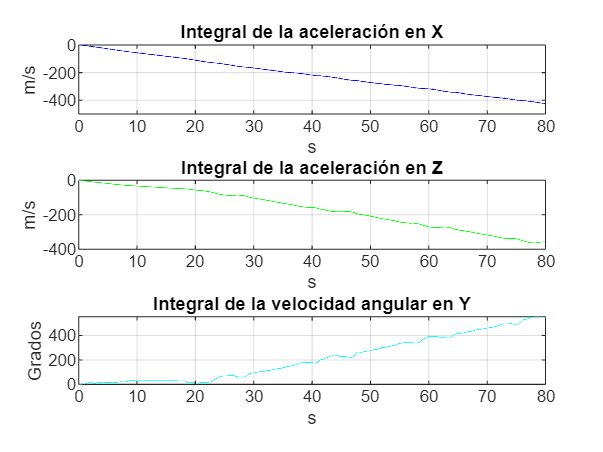


figure
subplot(3,1,1);
plot(t,vx,'b');
title('Integral de la aceleración en X');
xlabel('s');
ylabel('m/s');
grid on

subplot(3,1,2);
plot(t,vz,'g');
title('Integral de la aceleración en Z');
xlabel('s');
ylabel('m/s');
grid on

subplot(3,1,3);
plot(t,theta_y, 'c');
title('Integral de la velocidad angular en Y');
xlabel('s');
ylabel('Grados');
grid on

%x = zeros(size(length(norma_acc))); % Posición en x
%z = zeros(size(length(norma_acc))); % Posición en z

%Obtención de las posiciones en X y en Z para la trayectoria
x = zeros(size(length(norma_vel))); % Posición en x
z = zeros(size(length(norma_vel))); % Posición en z


%x = zeros(size(5000));
%z = zeros(size(5000));

for i = 2:length(norma_vel)
    x(i) = x(i-1) + norma_vel(i-1) * cosd(theta_y(i-1)) * t(i-1);
    z(i) = z(i-1) + norma_vel(i-1) * sind(theta_y(i-1)) * t(i-1) ;
end

% Mostrar resultados
disp('Posiciones en x:');

Posiciones en x:


disp(x);

   1.0e+07 *

  Columns 1 through 3.276

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

disp('Posiciones en z:');

Posiciones en z:


disp(y);

   1.0e+07 *

  Columns 1 through 3.276

         0         0         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

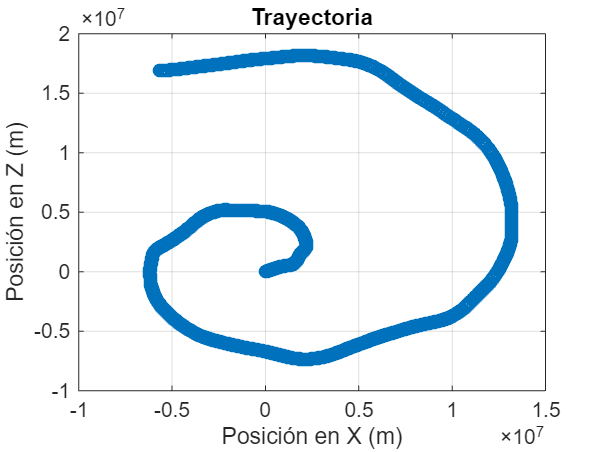


% Graficar trayectoria
figure;
plot(x, y, '-o');
xlabel('Posición en X (m)');
ylabel('Posición en Z (m)');
title('Trayectoria');
grid on;

% % Inicializamos el vector donde se almacenarán las normas
% norma_w = zeros(1, length(ax));
% 
% % Ciclo for para calcular la norma en cada instante
% for i = 1:length(ax)
%     norma_w(i) = sqrt(wx(i)^2 + wy(i)^2);
% end

% %vf=vo+a*t VELOCIDAD LINEAL
% 
% % Inicialización de la velocidad inicial
% v_i = 0; % Velocidad inicial
% 
% % Crear un vector para almacenar las velocidades finales
% v = zeros(size(axfilt)); % Un vector con el mismo tamaño que a
% 
% % Bucle iterativo para calcular la velocidad en cada paso
% for i = 1:length(axfilt)
%     v(i) = v_i + normas(i) .* t(i); % Calcula la velocidad final en este paso
%     v_i = v(i); % Actualiza la velocidad inicial para el siguiente cálculo
% end
% 
% figure
% plot(t,v)
% % El vector 'v' tendrá todas las velocidades calculadas
% 
% %VF=VO+A*T